*© 2023. Triad National Security, LLC. All rights reserved.*

*This program was produced under U.S. Government contract 89233218CNA000001 for Los Alamos*

*National Laboratory (LANL), which is operated by Triad National Security, LLC for the U.S.*

*Department of Energy/National Nuclear Security Administration. All rights in the program are.*

*reserved by Triad National Security, LLC, and the U.S. Department of Energy/National Nuclear*

*Security Administration. The Government is granted for itself and others acting on its behalf a*

*nonexclusive, paid-up, irrevocable worldwide license in this material to reproduce, prepare.*

*derivative works, distribute copies to the public, perform publicly and display publicly, and to permit.*

*others to do so.*

# Functional Analysis of Variance (F-ANOVA) Tutorial

This live script will go through several workflows to provide the analyst a variety of examples to learn from

F-ANOVA main purpose is to answer whether the mean response of functional data / curves are statistically different. The data set is partitioned by categorical variables.

For example, heart rate monitor data is measured multiple times over the time domain for the same person but under several different categorical conditions: hot, ambient, and cold air temperatures.

The main or primary factor being tested is air temperature. Within this factor are 3 different groups/levels of categorical variables:

- Hot

- Ambient

- Cold

 The null hypothesis, or default hypothesis, is that the categorical variables do not affect the mean functional response. The alternative hypothesis is that *at least* one of the categorical variables statistically changes the mean functional response. 

Load Data for all the Examples

DataStruct =  testFANOVA.GenerateExampleData();

### Sampled under a Common Domain

Building off the example above, the data has to be in a certain format for the class to work.  

The common domain over which all the functional data was collected was time. 

timeData=DataStruct(1).domainData;
disp(timeData([1, end]))  % Beginning and Ending of Time Data

     0    25



disp(uniquetol(diff(timeData), 1E-12))  % Time Step

    0.0100



fprintf("Number of Samples = %i", (numel(timeData))) % Total Number of Samples

Number of Samples = 2501

The data was collected starting at 0 Seconds and Ended after 25 seconds with increments of 0.010 seconds

### Funtional Data with MATLAB data structures

Functional Data collected during that common domain

Ex1_Data=DataStruct(1).Data;
disp(numel(Ex1_Data))  % Number of Cells

     3



Ex1_Data is a cell array of matrices. There are **3** cells, one for each level or categorical variable: **hot**, **ambient**, and **cold**.

disp(Ex1_Data)

    {2501×25 double}    {2501×25 double}    {2501×25 double}



Each cell contains a matrix of functional response data. 

-     Each column is a sample or replicate. There are 25 Replicates, thus 25 columns.

-     Each row represents the functional data collected at each discrete time step.  There are 2501 time steps, thus 2501 rows of data collected over each time step. 

### Using Echo Records

The class also supports utilizing another data structure called EnsembleRecords for users utilizing the Echo Data Analysis framework

if 8==exist('EnsembleRecord', 'class')
    labels = ["Cold", "Hot", "Ambient"];
    R = [];
    for K = 1:3  % Iterate over data and create EnsembleRecord
        r = EnsembleRecord(timeData, Ex1_Data{K});
        r.label('Temperature', labels(K))
        R = [R; r];
    end
    R = R.assignUnits('y', 'minute');
    R.setQuantity('y', 'Time', 'data', 'Heart Rate')

    Ens_labelTable = R.labelTable("-unsorted", "labelNames", "Temperature");
    disp(Ens_labelTable)

    data_bounds = [-inf, inf]
    GL = Ens_labelTable{:, 1};  % utilized unsorted Labels from Table

    MyEchoANOVA = functionalANOVA(R, data_bounds, GroupLabels=GL);

    MyEchoANOVA.PlotMeans('position', [90, 90, 700, 400])  % Show plotting with meta data included from records
    set(gcf,'Visible','on') % Forces External plotting which allows for transparency
end

## Instantiate an instance of the `funtionalANOVA` Class

Break down of the input arguments

- Pass in the cell aray of Data

- Pass in bounds from -inf to inf. Simply says don't subset the data. 

- Pass in the time array for which the data was sampled.

data_bounds =  [-inf, inf]; % Utilize the entire data set, dont subset the data
MyANOVA = functionalANOVA(Ex1_Data, data_bounds, d_grid=timeData);

#### Plot the Data to Verify Grouping

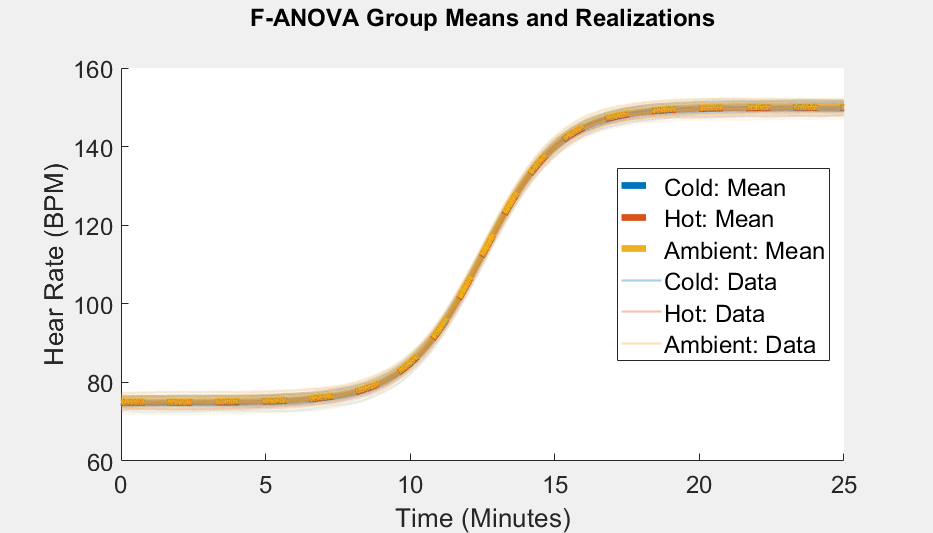

MyANOVA.PlotMeans('position', [90, 90, 700, 400], GroupLabels=["Cold", "Hot", "Ambient"])   % Plot the Data to verify Data and Domain
xlabel('Time (Minutes)')
ylabel('Hear Rate (BPM)')
set(gcf,'Visible','on') % Forces External plotting which allows for transparency

#### Subset Options

One can subset the data if they like. For example passing in  [10, 20] in the second argument position would subset the functional data between 10 and 20 seconds inclusive

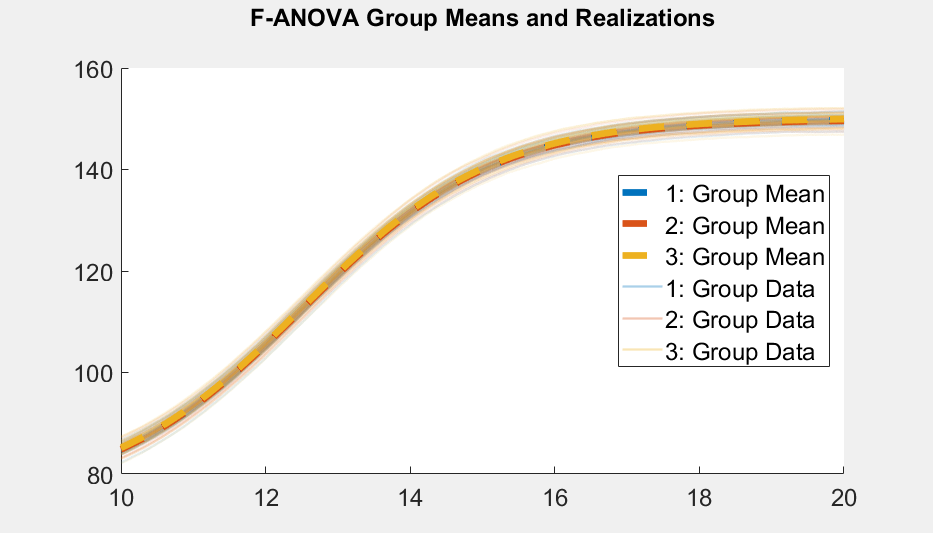

MyANOVA_Subset = functionalANOVA(Ex1_Data, [10, 20], d_grid=timeData);  
MyANOVA_Subset.PlotMeans('position', [90, 90, 700, 400]) % Plot the Data to verify subset of Data and Domain
set(gcf,'Visible','on')

The labels will be auto-generated if one doesn't prove them. Here groups are labels as simply 1 to 3.

## Check Assumptions of the Functional Data. Are the Covariances the Same?

We must first check whether the covariances are the same between all the levels or categorical variables. The type of F-ANOVA test depends on this assumption.

Run Covariance Test to check if the equality of the covariance functions are the same between all categorical variables

MyANOVA.CovarianceTest()

Unrecognized function or variable 'TimedProgressBar'.

Error in functionalANOVA/k_group_cov (line 148)
        ts = TimedProgressBar(self.N_permutations, 35, 'Running Permutation Test: ', 'Finished Permutation: ');

Error in functionalANOVA/CovarianceTest (line 1019)
                p_values(K) = self.k_group_cov(method, stat, Sigma, V);

All the different methods strongly suggest that one cannot reject the null hypothesis. The null hypothesis for this test is that the covariances are the same among all categorical levels.

This means this is a *homoscedastic* problem due to the *homogeneity* of the covariance functions 

Let's visualize the covariance results

MyANOVA.PlotCovariances(position=[90,257,1800,400])
set(gcf,'Visible','on')

Colors are different but the magnitudes are not that much different apart. Consistant pattern (or lack thereof) found among all the plots.  

## OneWay, Homoscedastic, Functional ANOVA

Perform OneWay F-ANOVA assuming *homoscedasticity or homogeneity* of covariances

MyANOVA.OneWayANOVA()

The results all agree that one cannot reject the null hypothesis. Our default alpha is 0.05.

*Since all the P-values are greater than 0.05, we can don't have enough evidence to reject our null hypothesis, that none of the categorical variables affects the mean functional response over the domain*

### Let's try another data set where the covariances are the same between groups, just like the example above.

The optional input argument,` GroupLabel`, can be used when instatiating the class or later on when running a class method such as,` OneWAYANOVA.`

Ex2_Data=DataStruct(2).Data;
MyANOVA = functionalANOVA(Ex2_Data, data_bounds, d_grid=timeData);  

% Run OneWayANOVA
MyANOVA.OneWayANOVA(GroupLabels=["Cold", "Hot", "Ambient"])  

The results all agree that one should reject the null hypothesis.

*Since all the P-values are less than 0.05, we have enough evidence to reject our null hypothesis, for the alternative hypothesis, that at least one categorical variable affects the mean functional response over the domain*

### A post-hoc analysis is required to investigate which level or categorie(s) affects the mean functional response. 

From the analysis above, all one knows is that at least one of the categorical variables statistically changes the mean functional response.

Setting the optional input argument, `hypothesis='pairwise'`, one can run all pair-wise F-ANOVAs between the categories to help analyze which categorial variables are statistically significant. 

MyANOVA.OneWayANOVA(hypothesis='pairwise')

Looking at the first column of the result table, the pair-wise response between hot and ambient conditions doesnt affect the mean response.

However, the cold categorical variable is statistically significant when paried against ambient or hot conditions. Therefore, we can conclude that the the cold categorical variable unanimously affects the mean functional response. 

Plotting the results provides visual evidence that the mean cold response is different compared to the others. One can see that the mean response under cold temperature shifts the mean response lower.

MyANOVA.PlotMeans('position', [90, 90, 700, 400], domainUnitsLabel='minutes', responseUnitsLabel='Beats per Minute', dataTransparency=0.05)   % Plot the Data to verify results
set(gcf,'Visible','on') % Forces External plotting which allows for transparency

## OneWay, Heteroscedastic, Functional ANOVA

Ex3_Data=DataStruct(3).Data;
My_BF_ANOVA = functionalANOVA(Ex3_Data, data_bounds, d_grid=timeData, GroupLabels=["Cold", "Hot", "Ambient"]);  

Check whether the covariances are the same between all the levels or categorical variables. Run Covariance test.

My_BF_ANOVA.CovarianceTest

All the different methods strongly suggest that one should reject the null hypothesis for the alternative, at least one covariance function(matrix) is different

This means this is a *heteroscedastic* problem due to the *nonhomogeneity* of the covariance functions 

My_BF_ANOVA.PlotCovariances(position=[90,257,1600,500], responseUnitsLabel='BPM', domainUnitsLabel='minutes')

Plot also shows vastly different covariances. From diagonal to constant with different magnitudes.

My_BF_ANOVA.PlotMeans('position', [90, 90, 700, 400], dataTransparency=0.1)
set(gcf,'Visible','on') % Forces External plotting which allows for transparency

My_BF_ANOVA.PlotMeans('position', [90, 90, 700, 400], dataTransparency=0.1)
xlim([0, 5])
set(gcf,'Visible','on') % Forces External plotting which allows for transparency

Subset shown to show the *heteroscedastic *nature of the data

Perform OneWay F-ANOVA assuming *heteroscedasticity or nonhomogeneity* of covariances for **Behrens–Fisher (BF) **type problems using: `OneWayANOVA_BF()`

My_BF_ANOVA.OneWayANOVA_BF(alpha=0.01)

Even with the vastly different covariances between the groups/levels, the results all agree that one cannot reject the null hypothesis.

*Since all the P-values are greater than 0.01, we can don't have enough evidence to reject our null hypothesis, that none of the categorical variables affects the mean functional response over the domain*

P-values and confidence and related by: Confidence = 1 - α.  If one wants 99% confidence, then set alpha=1-0.99 = 0.01

## Two-Way F-ANOVA

TwoWay ANOVA has nested categorical variables. In the following data set there are 2 different factors that are being studied.

- The first factor, denoted as the primary factor, has two categorical variables: **bladder** or **bottle**. This denotes whether the individual used a hydration bladder compared to a water botte. 

- the second factor, denoted as the secondary factor, has four categorical variables: **pants**, **shorts**, **skirt**, or a **Dress**. This denotes what the individual wore when performing the experiment.

Which factor is the primary or second doesnt matter, it is purely for "bookkeeping". However, the primary factor must be organized as a cell array of matrices. To denote the which sample corresponds to the seconday factor, an indicator cell or array must be provided

Ex4_Data=DataStruct(4).Data;
IndicatorCell = DataStruct(4).IndicatorCell;
disp(Ex4_Data)

Since there are 2 levels within the primary factor, there are 2 elements within the cell array. Each Matix within the cell represents the response and replicates due to the primary factor.

disp(IndicatorCell)

Since there are 2 levels within the primary factor, there are 2 elements within the cell array. Each array within the cell represents which sample belongs to which secondary factor level. 

 All together there was 120 samples. Thus, the entire length of all indicator arrays is also 120. 

disp(unique(IndicatorCell{1}))

Here it can be shown that there were 4 different levels nested into the first categorical variable from the primary factor.

Master_Indicator = reshape(cell2mat(IndicatorCell), 120, 1);
disp(size(Master_Indicator))

The class also supports one entire Indicator array instead of the cell array of indicators. Either way, one must pass in some form of an indicator into the class for it to denote the sub-structure of the data.

#### Instantiate the class for TwoWay ANOVA

MyTwoWayANOVA = functionalANOVA(Ex4_Data, data_bounds, d_grid=timeData, ...
    PrimaryLabels=["Bladder", "Bottle"], ...
    SecondaryLabels=["Pants", "Shorts", "Skirt", "Dress"], ...
    SubgroupIndicator=Master_Indicator);  

#### Check Assumptions of the Functional Data

MyTwoWayANOVA.CovarianceTest

All the different methods strongly suggest that one cannot reject the null hypothesis. The null hypothesis for this test is that the covariances are the same among all categorical levels.

This means this is a *homoscedastic* problem due to the *homogeneity* of the covariance functions 

TwoWay data sets are inherently more complicated due to the experiment design. Among the family wise and pair-wise hypotheses, one can also investigate if the primary, secondary, or interaction of the these affect mean response. 

Assessing whether *any* levels within the experiment affects the mean response.

MyTwoWayANOVA.TwoWayANOVA()

*It appears at least one of the levels within either or both of the factors affects the mean.*

More investigation is required to assert which level/group within the factors is causing this.

Assessing whether the primary factor (bladder or bottle) affects the mean response

MyTwoWayANOVA.TwoWayANOVA(hypothesis="primary")

It appears the primary factor *doesnt* affect the mean response.

Assessing whether the secondary factor, clothing choice (pants, shorts, skirt, or a Dress),  affects the mean response

MyTwoWayANOVA.TwoWayANOVA(hypothesis="secondary")

It appears the secondary factor *does* affect the mean response. However more analysis is required as to which level(s)/group(s) affect the mean response

Assessing whether the interaction between the primary and seconday factors affects the mean response

MyTwoWayANOVA.TwoWayANOVA(hypothesis="interaction")

It appears there is no interacton effect between the two factors.

Run pairwise combinatorial hypothesis to see which levels affect the mean response. 

2 levels within the primary factor and 4 levels within the secondary factor means 8 total combinations of groupings.

`28 = nchoosek(8, 2), `number of pair-wise tests to run

Run a subset of the methods to save on computational time

MyTwoWayANOVA.TwoWayANOVA(hypothesis="pairwise", ANOVA_Methods = ["L2-Simul", 'F-Simul'])

It appears that wearing pants compared to the other clothing choices affects the mean response. One can test this hypothesis with a contrast test

#### Contrast Tests

Contrast tests allow the testing for a specific hypothesis. The contrat vector must be the same number of elements as the number of categorical levels within a factor. If both primary and secondar factor have the same number of levels, the class will prompt which factor to apply the contrast test to.

- Primary Factor Contrast Vector: The first element of the contrast vector refers to the categorical level from first cell array, and so on... 

- Secondary Factor Contrast Vector: The first element of the contrast vector refers to the first, ranked and ordered, indicator. And so on...

Here, the test is to determine if **pants**, a level within the seconday factor, compared to all the other levels (**shorts**, **skirt**, and **Dress**) is significant. Since there are 4 levels, the contrat vector must be 4 elements long. The contrast vector must sum to 0 as the null hypothesis posits that none of the levels are statistically significant. 

Setting the other levels to -1, requires setting pants to 3 in order for the contrast vector to sum to 0. 

MyTwoWayANOVA.TwoWayANOVA(hypothesis="custom", ANOVA_Methods = ["L2-Simul", 'F-Simul'],  Contrast = [3, -1, -1, -1])

One finds that **pants** compared to **shorts**, **skirt**, and **Dress **is statistically significant, just as the pair-wise tests was trying to ellucidate. 

plotMeans and plotovariances for TwoWay analysis supports the `plotType` input argument. Options are "`primary"`, "`secondary"`, or "`interaction".`

MyTwoWayANOVA.PlotMeans(plotType='secondary', position=[90, 90, 700, 400], dataTransparency=0.1, responseUnitsLabel='BPM', domainUnitsLabel='minutes')
set(gcf,'Visible','on') % Forces External plotting which allows for transparency

The plot supports the statistical analysis above, it apppears wearing pants does affect the mean heart rate.